%Load source audio
%Options: gong, chirp, handel, laughter, splat, train

load chirp
y1=y; Fs1=Fs;


load gong
y2=y; Fs2=Fs;

%Must be same size
lengths=[length(y1),length(y2)];
l = 2000;
%l=min(lengths);
%Unmixed matrix
S=[y1(1:l,:), y2(1:l,:)];

%Mixes withOUT random offset
A1 = randn(2);
M=S*A1; %+randn(size(S));
M = M'

M =     0.0008    0.0009    0.0016    0.0044    0.0018    0.0048    0.0064    0.0035    0.0070    0.0010   -0.0007   -0.0003   -0.0044   -0.0031   -0.0070   -0.0094   -0.0078   -0.0093   -0.0130   -0.0091   -0.0151   -0.0112   -0.0116   -0.0191   -0.0093   -0.0174   -0.0071    0.0013    0.0008    0.0170    0.0117    0.0147    0.0191   -0.0007    0.0161    0.0063    0.0040    0.0198   -0.0128    0.0164   -0.0053   -0.0036    0.0190   -0.0136    0.0251    0.0074    0.0055    0.0295   -0.0103    0.0253
   -0.0030   -0.0013   -0.0033   -0.0212    0.0017   -0.0160   -0.0229    0.0001   -0.0304    0.0039    0.0002   -0.0102    0.0199   -0.0061    0.0113    0.0237    0.0062    0.0182    0.0411    0.0020    0.0495    0.0184    0.0128    0.0679   -0.0151    0.0548    0.0008   -0.0144    0.0428   -0.0560    0.0098   -0.0148   -0.0723    0.0664   -0.0679    0.0052    0.0265   -0.1089    0.1287   -0.1146    0.0492    0.0361   -0.1309    0.1514   -0.1347    0.0161    0.0357   -0.1608    0.1536   -0

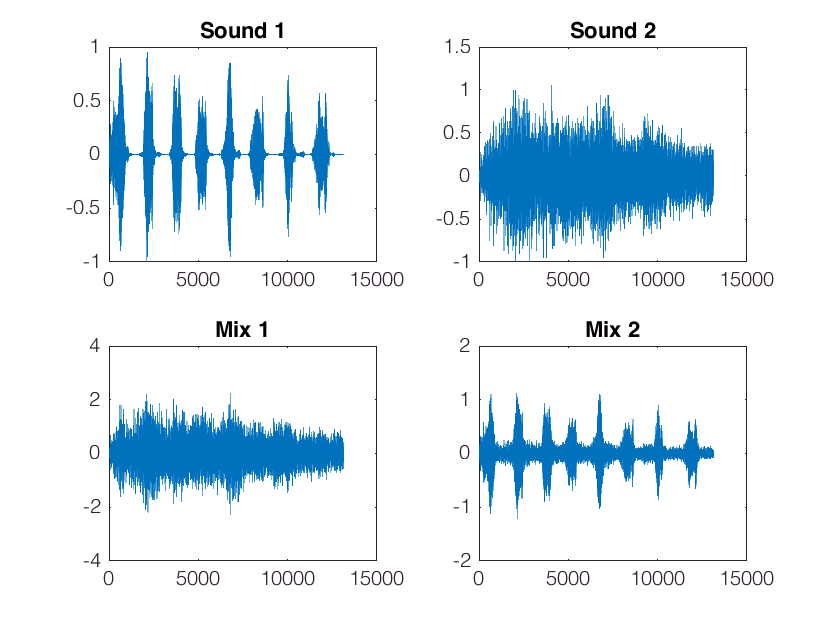

%Plot sounds and the mixes
subplot(2,2,1)
plot(S(:,1))
title('Sound 1')

subplot(2,2,2)
plot(S(:,2))
title('Sound 2');

subplot(2,2,3)
plot(M(:,1))
title('Mix 1')

subplot(2,2,4)
plot(M(:,2))
title('Mix 2')

%Pre-processing

% 
% %Centering M - subtract out means (add back in later)
% means = [mean(M(:,1)),mean(M(:,2))];
% Mc = M - repmat(means,l,1);
% 
% %Whiten mixed signals
% %EVD of covariance matrix of M
% covM=cov(Mc',1);
% [E,D]=eig(covM);

Error using svd
Out of memory. Type HELP MEMORY for your options.

% D2=sqrt(D)';
% whiteningMatrix = inv(D2)*E2';
% dewhiteningMatrix = E*D2;
% %whitenedM=(E*D2*E.'*Mc')';
% % covM
% % E
% % size(whiteningMatrix)
% % size(Mc)
% whitenedM = whiteningMatrix*Mc

[Mw, whiteningMatrix, dewhiteningMatrix, means] = preprocessing(M);

[A, W] = ica(whiteningMatrix, dewhiteningMatrix, Mw, means);

icasig = W * M + (W * means) * ones(1, l);

%Do ICA!

%Nonquadratic functions used to estimate negentropy
%g1=
%g2=

%Choose random initial weight vector w
%w=randn(2);

%convergence=0;
%while convergence==0;
    %wp=mean(whitenedM*g*(transpose(w)*whitenedM))-mean(gp*(transpose(w)*x))*w;
    %w=wp/norm(wp);
    
    %check for convergence:
    %c=dot(w,wp);
    %if abs(c)-1 <= 0.05
        %convergence=1;
    %end
%end

%Separate mixes
%Y=transpose(w)*whitenedM;

%Add means back in
%Y=Y+repmat(means,l,1);

%Play all sounds - original, mixed, unmixed

%Original
%sound(S(:,1),Fs)
%sound(S(:,2),Fs)

%Mixed
%sound(M(:,1),Fs)
%sound(M(:,2),Fs)

%Unmixed
%sound(Y(:,1),Fs)
%sound(Y(:,2),Fs)

